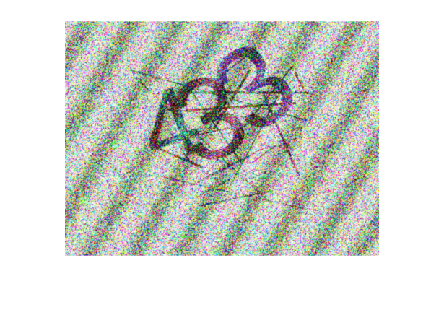

I = imread('Train/captcha_0003.png');
imshow(I)

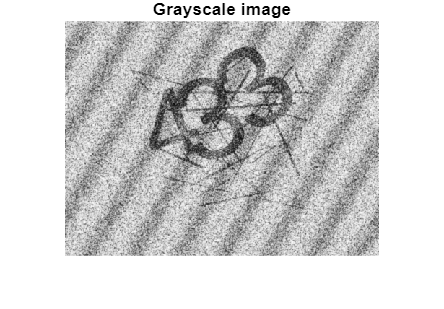

I_gray = rgb2gray(I);
imshow(I_gray)
title("Grayscale image")

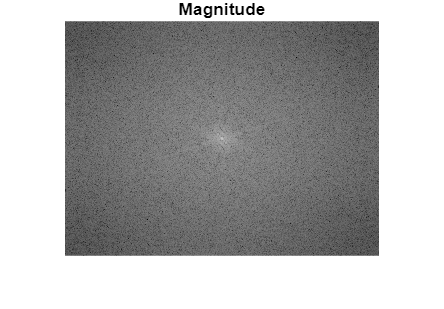


%Fourier transform
fft = fft2(double(I_gray));
fftshifted = fftshift(fft);

magnitude = log(abs(fftshifted) + 1);
imshow(magnitude, []);
title("Magnitude")

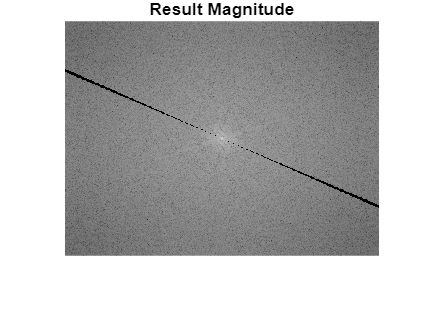


size_image = size(magnitude);

tan_min = tan(deg2rad(66));
tan_max = tan(deg2rad(67));

for i = 1:size_image(1)
    for j = 1:size_image(2)
        tangent = (j - round(0.5 * size_image(2)))/(i - round(0.5 * size_image(1)));     
        if tangent > tan_min  && tangent < tan_max
            fftshifted(i,j) = 0;
        end 
    end 
end 

magnitude = log(abs(fftshifted) + 1);
imshow(magnitude, []);
title("Result Magnitude")

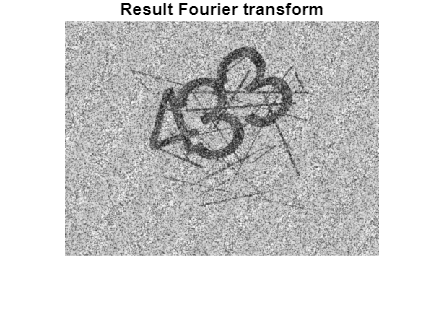


ifftshifted = ifftshift(fftshifted);
res = uint8(ifft2(ifftshifted));
imshow(res);
title("Result Fourier transform")

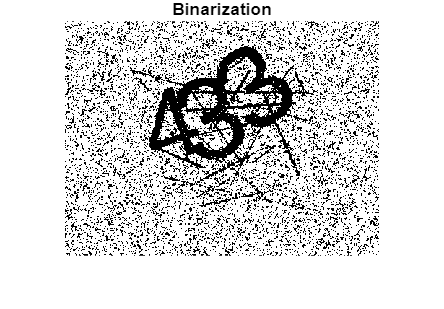


%Binarization
I_binary = imbinarize(res);
imshow(I_binary);
title("Binarization")

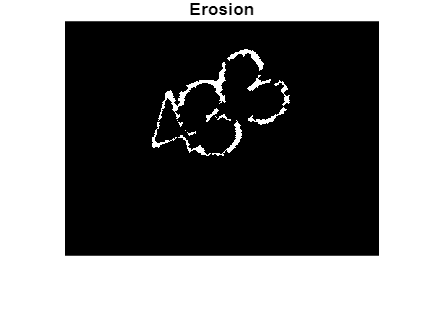

I_binary = ~I_binary;


%Erosion
se = strel("diamond",4);
I_eroded = imerode(I_binary,se);
imshow(I_eroded);
title("Erosion")

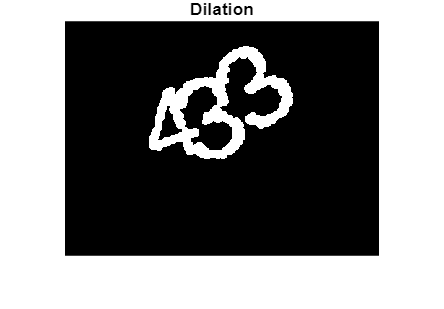



%Dilation
se = strel("disk",5);
I_dilated = imdilate(I_eroded,se);
imshow(I_dilated);
title("Dilation")

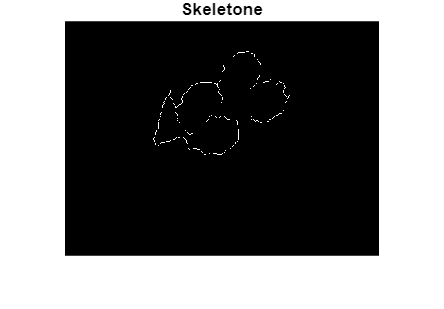



%Skeletone
I_skel = bwskel(I_eroded,'MinBranchLength',4);
imshow(I_skel );
title("Skeletone");